# **Entregable 1**

clear; clc;

% Tamaño del espacio
m = 3;

% Resolución o incremento entre puntos (que tan denso)
dm = 0.3; 

[x,y,z] = meshgrid(-m:dm:m);

**Posición de la Partícula**

% Positiva
posP = [-1.5, 0, 0];

% Negativa
posN = [1.5, 0, 0];

**Dibujo de las cargas**

% Cargas
% radio = 0.3;
% 
% [xx, yy, zz] = sphere(20);
% esfera1 = surf(radio*xx + posP(1), radio*yy + posP(2), radio*zz + posP(3));
% esfera1.FaceColor = 'red';
% hold on;
% 
% esfera2 = surf(radio*xx + posN(1), radio*yy + posN(2), radio*zz + posN(3));
% esfera2.FaceColor = 'blue';
% 
% axis equal;

**Campo Eléctrico**


$$\overset{\longrightarrow }{E} =k\frac{q}{r^3 }\left(\mathrm{xi}+\mathrm{yi}\right)$$


% Variables
q1 = 3;
q2 = -3;

**Cálculos**

% Distancia a la carga negativa
r1 = sqrt((x-posP(1)).^2 + (y-posP(2)).^2); 

% % Distancia a la carga positiva
r2 = sqrt((x-posN(1)).^2 + (y-posN(2)).^2); 

% % Componentes del campo eléctrico en x, y, z
Ex = (q1*(x-posP(1))./r1.^3 + q2*(x-posN(1))./r2.^3); 
Ey = (q1*(y-posP(2))./r1.^3 + q2*(y-posN(2))./r2.^3); 
Ez = (q1*(z-posP(3))./r1.^3 + q2*(z-posN(3))./r2.^3); 

% Direcciones
E = sqrt(Ex.^2 + Ey.^2 + Ez.^2);
Ex = Ex./E;
Ey = Ey./E;
Ez = Ez./E;

**Graficación del campo**

quiver3(x,y,z,Ex,Ey,Ez);
title("Vista 3D del comportamiento de las cargas");
grid on;
axis equal;

**Dibujo de las placas**

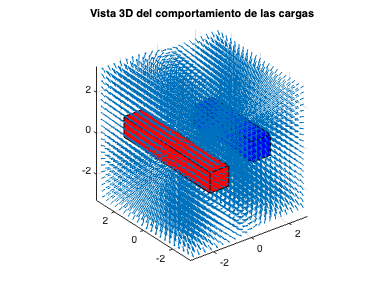

% Placa positiva
x = [-m+2 -m+1 -m+1 -m+2 -m+2 -m+1 -m+1 -m+2];
y = [-m -m m m -m -m m m];
z = [-0.5 -0.5 -0.5 -0.5 0.5 0.5 0.5 0.5];
f = [1 2 3 4; 5 6 7 8; 1 2 6 5; 2 3 7 6; 3 4 8 7; 4 1 5 8];
patch('XData',x,'YData',y,'ZData',z,'Faces',f,'FaceColor','red')

% Placa negativa
x = [m-2 m-1 m-1 m-2 m-2 m-1 m-1 m-2];
y = [-m+1 -m+1 m-1 m-1 -m+1 -m+1 m-1 m-1];
z = [-0.5 -0.5 -0.5 -0.5 0.5 0.5 0.5 0.5];
f = [1 2 3 4; 5 6 7 8; 1 2 6 5; 2 3 7 6; 3 4 8 7; 4 1 5 8];
patch('XData',x,'YData',y,'ZData',z,'Faces',f,'FaceColor','blue')
view(3)
hold on;

**Glóbulos de los virus**

% Definir los valores de y
y = [-m:0.1:m];
x = [0:-0.1:-0.75-d];

Unrecognized function or variable 'd'.

x2 = ones(1,numel(y) - numel(x)).* -0.75-d;
x = [x x2];


z = zeros(size(y));

% Cargar la esfera
radio = 0.3;
[xx, yy, zz] = sphere(20);

% Graficar la esfera inicial
esfera1 = surf(radio*xx + x(1), radio*yy + y(1), radio*zz + z(1));
esfera1.FaceColor = 'green';

m = 3;
for i = 1:numel(y)
    % Actualizar las coordenadas de la esfera

    set(esfera1, 'XData', radio*xx + x(i), 'YData', radio*yy + y(i), 'ZData', radio*zz + z(i));
    drawnow; % Actualizar la pantalla
    
    % Esperar un tiempo entre cada iteración para que la animación se vea más lenta
    pause(0.1);
end